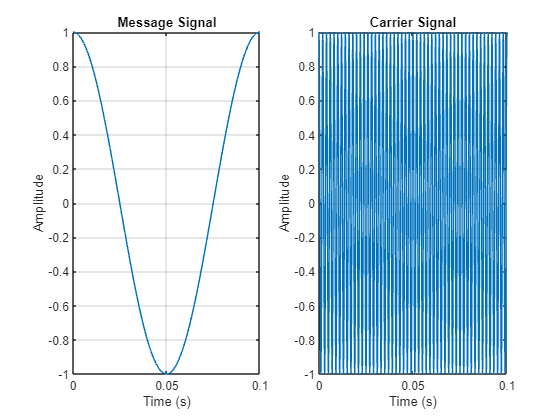

% Parameters
fm = 10;         % Message signal frequency (Hz)
Am = 1;          % Message signal amplitude
theta_m = 0;     % Message signal phase
fs = 10000;      % Sampling frequency
fc = 500;        % Carrier frequency (Hz)
Ac = 1;          % Carrier amplitude
theta_c = 0;     % Carrier phase
freq_dev = 250;  % Frequency deviation factor

% Time scale
t = 0:1/fs:0.1;  % Time scale for one time period of the message signal

% Message signal
message_signal = Am * cos(2*pi*fm*t + theta_m);

% Modulation
modulated_signal = fmmod(message_signal, fc, fs, freq_dev);

% Demodulation
demodulated_signal = fmdemod(modulated_signal, fc, fs, freq_dev);

% Magnitude spectrum of input signal
input_spectrum = abs(fft(message_signal));

% Magnitude spectrum of demodulated signal
demodulated_spectrum = abs(fft(demodulated_signal));

% Magnitude spectrum of modulated signal
modulated_spectrum = abs(fft(modulated_signal));


% Carrier signal
carrier_signal = Ac * cos(2*pi*fc*t + theta_c);

% Plotting
figure;
subplot(1,2,1);
plot(t, message_signal);
title('Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(1,2,2);
plot(t, carrier_signal);
title('Carrier Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

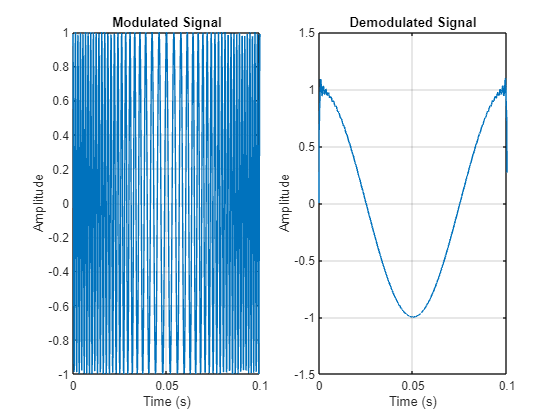



figure

subplot(1,2,1);
plot(t, modulated_signal);
title('Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(1,2,2);
plot(t, demodulated_signal);
title('Demodulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

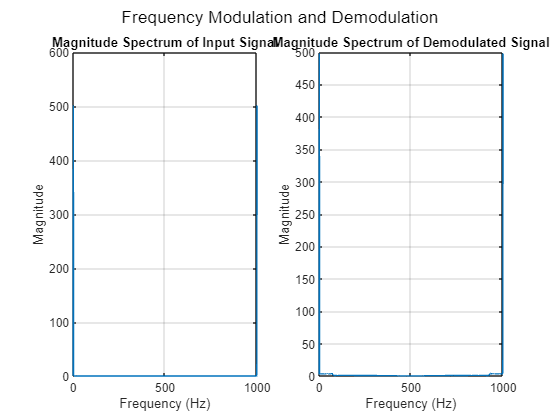




figure;

subplot(1,2,1);
plot(abs(input_spectrum));
title('Magnitude Spectrum of Input Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(1,2,2);
plot(abs(demodulated_spectrum));
title('Magnitude Spectrum of Demodulated Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Adjusting layout
sgtitle('Frequency Modulation and Demodulation');

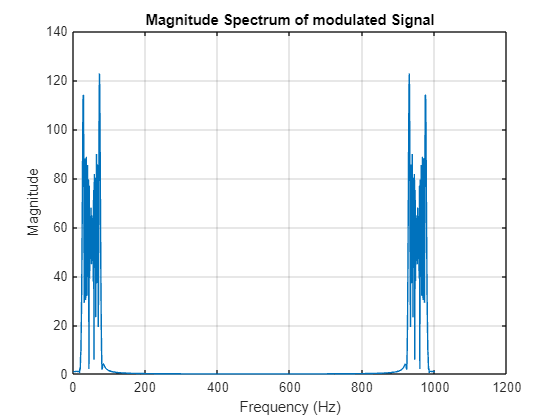


figure
plot(abs(modulated_spectrum));
title('Magnitude Spectrum of modulated Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;